# [4.3. Полевой транзистор (ПТ)](https://ru.wikipedia.org/wiki/Полевой_транзистор)

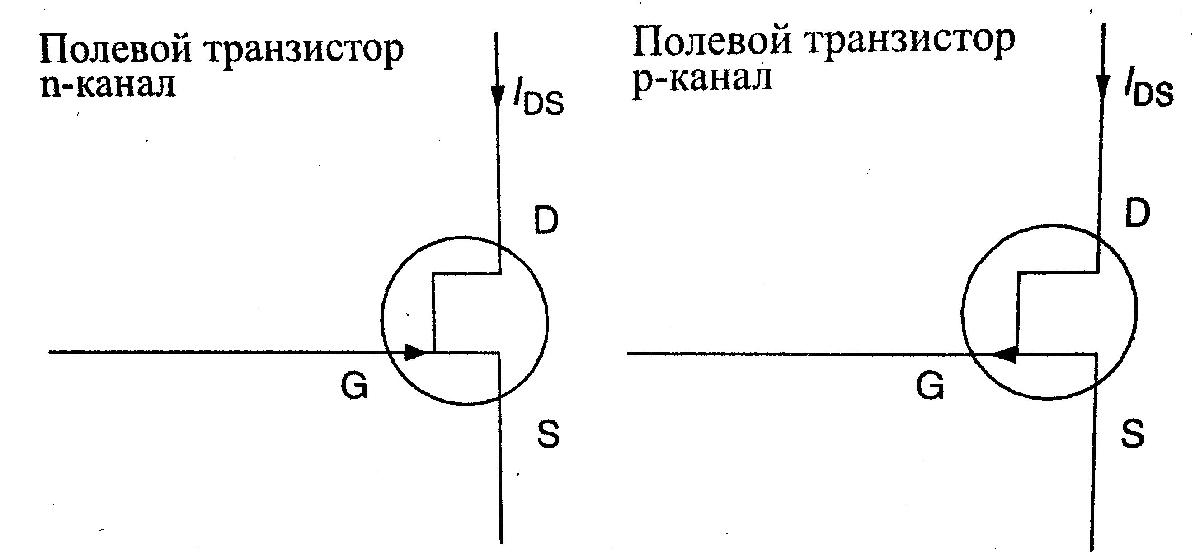

#### Низкочастотная эквивалентная цепь

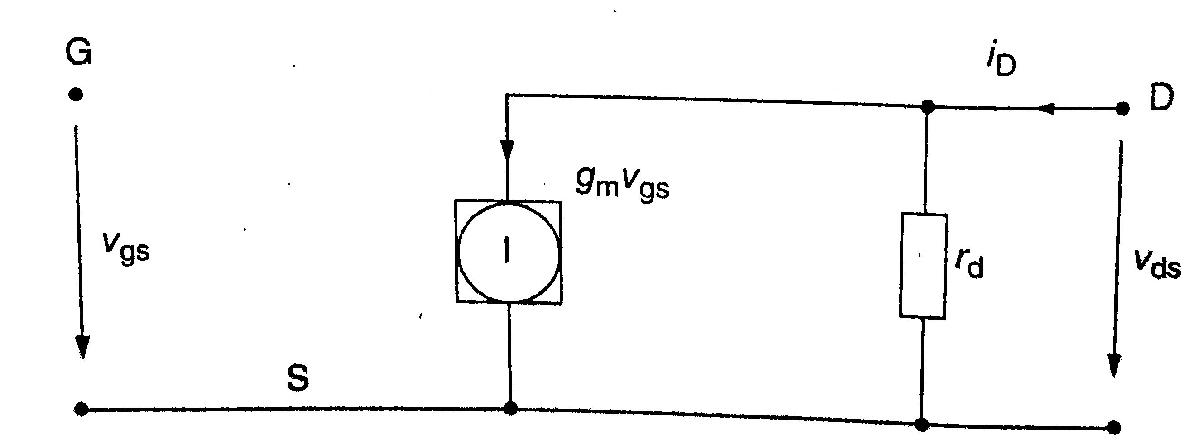

clear
syms i_d g_m v_gs r_d v_ds
i_d==g_m*v_gs+1/r_d*v_ds

$$ans = i_{d}=g_{m}\,v_{\mathrm{gs}}+\frac{v_{\mathrm{ds}}}{r_{d}}$$

% g_m = крутизна транзистора
% r_d = сопротивление стока транзистора

#### Тип стока

syms I_DS I_DSS V_GS V_p
I_DS==I_DSS*(1-V_GS/V_p)^2

$$ans = I_{\mathrm{DS}}=I_{\mathrm{DSS}}\,{\left(\frac{V_{\mathrm{GS}}}{V_{p}}-1\right)}^{2}$$

% I_DSS = ток стока насыщения, если V_GS=0
% V_p = напряжение смыкания

#### Коэффициент усиления незамкнутого контура

syms mu V_DS(V_GS,I_D) v_ds v_gs i_d r_d g_m
mu==diff(V_DS,V_GS)... % |I_D
    ==-v_ds/v_gs...    % |i_d=0
    ==r_d*g_m

$$ans(V\_GS, I\_D) = \left(\left(\mu =\frac{\partial }{\partial V_{\mathrm{GS}}}V_{\mathrm{DS}}\left(V_{\mathrm{GS}},I_{D}\right)\right)=-\frac{v_{\mathrm{ds}}}{v_{\mathrm{gs}}}\right)=g_{m}\,r_{d}$$

#### Крутизна


$$g_m =\frac{\partial }{\partial V_{\mathrm{GS}} }I_D |_{V_{\mathrm{DS}} } =\frac{i_D }{v_{\mathrm{gs}} }|_{v_{\mathrm{ds}} =0} =g_{\mathrm{m0}} {\left(1-\frac{V_{\mathrm{GS}} }{V_p }\right)}^2 =-\frac{2}{V_p }\sqrt{I_{\mathrm{DSS}} I_{\mathrm{DS}} }$$


syms g_m I_D(V_GS,V_DS) i_d v_gs g_m0 V_GS V_p I_DSS I_DS
g_m==diff(I_D,V_GS) ...  % |V_DS
    ==i_d/v_gs ...       % |v_ds=0
    ==g_m0*(1-V_GS/V_p)^2 ...
    ==-2/V_p*sqrt(I_DSS*I_DS)

$$ans(V\_GS, V\_DS) = \left(\left(\left(g_{m}=\frac{\partial }{\partial V_{\mathrm{GS}}}I_{D}\left(V_{\mathrm{GS}},V_{\mathrm{DS}}\right)\right)=\frac{i_{d}}{v_{\mathrm{gs}}}\right)=g_{\mathrm{m0}}\,{\left(\frac{V_{\mathrm{GS}}}{V_{p}}-1\right)}^{2}\right)=-\frac{2\,\sqrt{I_{\mathrm{DS}}\,I_{\mathrm{DSS}}}}{V_{p}}$$

#### Карта соотношений вход/выход для транзисторов

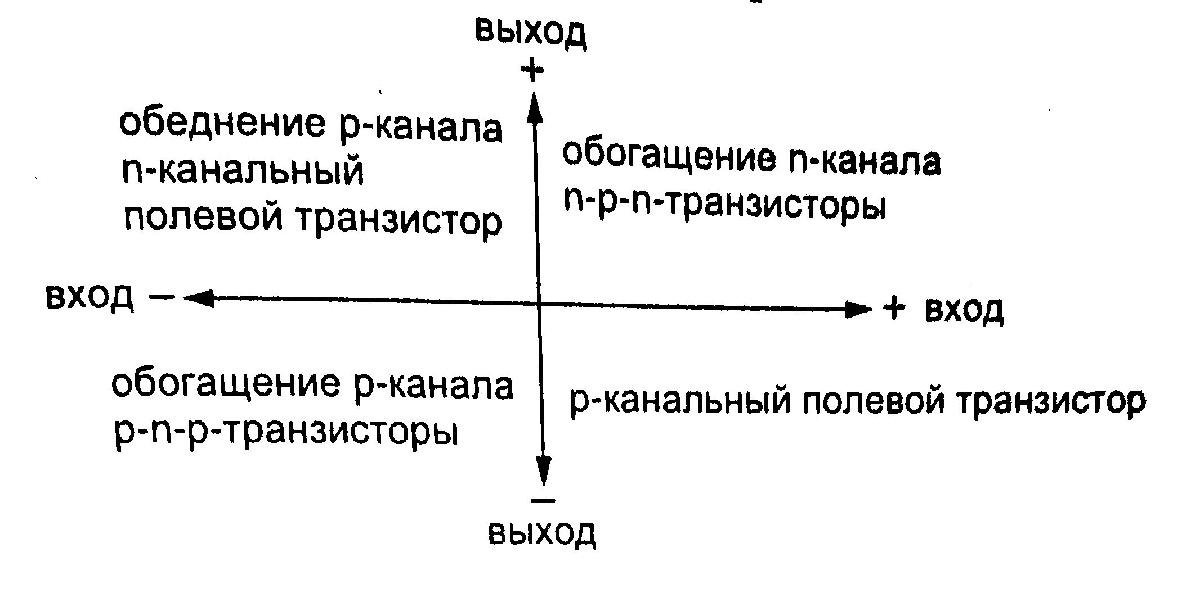

#### МОП-транзистор